1. Un automobil care se deplaseaza pe un drum drept este cronometrat in mai multe puncte. Datele de observatie se dau in tabela de mai jos. Utilizati interpolarea Hermite pentru a prevedea pozitia si viteza automobilului la momentul $t=10$.

x = [0 3 5 8 13];
f = [0 225 383 623 993];
df = [75 77 80 74 72];    

xx = [10];
[yy,vv] = interpolareHermiteWithDerivative(x, f, df, xx)

yy = 742.5028

vv = 48.3817

yt = exp(xx)

yt = 2.2026e+04


clf
hold on
t = linspace(0,15);
[y,v]=interpolareHermiteWithDerivative(x,f,df,t)

y = 	1.0e+03 *

         0    0.0115    0.0231    0.0348    0.0465    0.0580    0.0694    0.0808    0.0920    0.1032    0.1143    0.1254    0.1365    0.1476    0.1587    0.1700    0.1813    0.1927    0.2041    0.2157    0.2273    0.2391    0.2508    0.2627    0.2746    0.2865    0.2985    0.3105    0.3226    0.3346    0.3467    0.3588    0.3709    0.3830    0.3951    0.4073    0.4195    0.4317    0.4439    0.4561    0.4684    0.4807    0.4931    0.5054    0.5177    0.5301    0.5424    0.5546    0.5667    0.5788


v = 	1.0e+03 *

    0.0750    0.0765    0.0771    0.0770    0.0765    0.0759    0.0751    0.0744    0.0739    0.0734    0.0732    0.0732    0.0733    0.0735    0.0739    0.0744    0.0749    0.0754    0.0760    0.0766    0.0771    0.0776    0.0780    0.0784    0.0787    0.0790    0.0792    0.0794    0.0795    0.0796    0.0797    0.0798    0.0799    0.0800    0.0801    0.0803    0.0804    0.0806    0.0808    0.0810    0.0812    0.0813    0.0814    0.0815    0.0814    0.0812    0.0809    0.0805    0.0799    0.0791


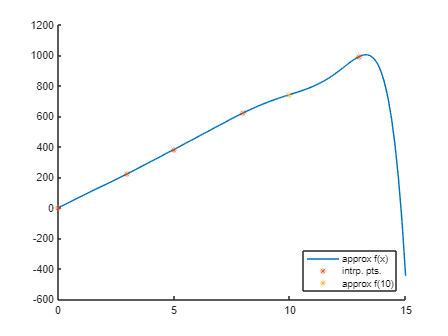

plot(t, y)
scatter(x,f,'marker','*')
scatter(xx,yy,'marker','*')
legend(["approx f(x)","intrp. pts.","approx f(10)"],'Location','southeast')
hold off

function [ H, dH] = interpolareHermiteWithDerivative( x, f, fd, X )
	coefs=dif_div_duble(x,f,fd);
    
    coefs=coefs(1,:);
    
	z=repelem(x,2);
	H=X; 
	dH=X;
    for k=1:length(X)
          P=1; DP=0; 
      H(k)=coefs(1)*P; dH(k)=0;
      
      for i=2:length(coefs)
       DP=DP*(X(k)-z(i-1))+P;
       P=P*(X(k)-z(i-1));
       H(k)=H(k)+coefs(i)*P;
       dH(k)=dH(k)+coefs(i)*DP;
      end
    end
end

function T=dif_div_duble(x,f,df)
	T=NaN(2*length(x));
	z=repelem(x,2);
	T(:,1)=repelem(f,2);
	T(1:2:end-1,2)=df;
	T(2:2:end-2,2)=diff(f)./diff(x);
	for j=3:length(z)
		 T(1:end-j+1,j)=diff(T(1:end-j+2,j-1))./(z(j:end)-z(1:end-j+1))';
    end
end


